## 产品质量管理项目

#### 首先随机生成25组 每组五个样本

% 产品质量管理项目

% 初始化数据
data = [
    12.4, 12.6, 12.3, 12.7, 12.1;
    12.7, 12.8, 12.6, 12.5, 12.9;
    12.5, 12.3, 12.4, 12.6, 12.5;
    12.6, 12.5, 12.7, 12.4, 12.6;
    12.2, 12.4, 12.3, 12.5, 12.2;
    12.8, 12.9, 12.7, 12.6, 12.8;
    12.3, 12.4, 12.2, 12.3, 12.4;
    12.6, 12.7, 12.5, 12.8, 12.6;
    12.5, 12.6, 12.4, 12.5, 12.6;
    12.7, 12.8, 12.7, 12.6, 12.8;
    12.4, 12.5, 12.3, 12.6, 12.4;
    12.8, 12.9, 12.8, 12.7, 12.9;
    12.3, 12.4, 12.2, 12.3, 12.4;
    12.7, 12.8, 12.6, 12.7, 12.8;
    12.4, 12.5, 12.3, 12.6, 12.4;
    12.6, 12.7, 12.5, 12.8, 12.6;
    12.5, 12.6, 12.4, 12.5, 12.6;
    12.7, 12.8, 12.7, 12.6, 12.8;
    12.4, 12.5, 12.3, 12.6, 12.4;
    12.8, 12.9, 12.8, 12.7, 12.9;
    12.3, 12.4, 12.2, 12.3, 12.4;
    12.7, 12.8, 12.6, 12.7, 12.8;
    12.5, 12.6, 12.4, 12.5, 12.6;
    12.6, 12.7, 12.5, 12.8, 12.6;
    12.4, 12.5, 12.3, 12.6, 12.4;
];

% 描述性统计分析
mean_values = mean(data, 2);
var_values = var(data, 0, 2);
range_values = range(data, 2);
stds_values = std(data, 0, 2);

disp('描述性统计结果:');

描述性统计结果:


disp(['组均值: ', num2str(mean_values')]);

组均值: 12.42         12.7        12.46        12.56        12.32        12.76        12.32        12.64        12.52        12.72        12.44        12.82        12.32        12.72        12.44        12.64        12.52        12.72        12.44        12.82        12.32        12.72        12.52        12.64        12.44


disp(['组方差: ', num2str(var_values')]);

组方差: 0.057       0.025       0.013       0.013       0.017       0.013       0.007       0.013       0.007       0.007       0.013       0.007       0.007       0.007       0.013       0.013       0.007       0.007       0.013       0.007       0.007       0.007       0.007       0.013       0.013


disp(['组标准差: ', num2str(stds_values')]);

组标准差: 0.23875     0.15811     0.11402     0.11402     0.13038     0.11402    0.083666     0.11402    0.083666    0.083666     0.11402    0.083666    0.083666    0.083666     0.11402     0.11402    0.083666    0.083666     0.11402    0.083666    0.083666    0.083666    0.083666     0.11402     0.11402


disp(['组极差: ', num2str(range_values')]);

组极差: 0.6         0.4         0.3         0.3         0.3         0.3         0.2         0.3         0.2         0.2         0.3         0.2         0.2         0.2         0.3         0.3         0.2         0.2         0.3         0.2         0.2         0.2         0.2         0.3         0.3



all_mean = mean(data(:)); % 总体均值
all_variance = var(data(:)); % 总体方差
all_range = range(data(:)); % 总体极差
all_std = std(data(:));

disp('总体描述性统计结果:');

总体描述性统计结果:


disp(['总体均值: ', num2str(all_mean)]);

总体均值: 12.5576


disp(['总体方差: ', num2str(all_variance)]);

总体方差: 0.035849


disp(['总体标准差: ', num2str(all_std)]);

总体标准差: 0.18934


disp(['总体极差: ', num2str(all_range)]);

总体极差: 0.8





% 绘制直方图
figure;


% 绘制直方图并设置边界
h = histogram(data);
% 获取各组的边界
binEdges = h.BinEdges;

% 获取各组的宽度
binWidth = h.BinWidth;

% 获取各组的频数
binCounts = h.Values;
% 获取分组数
numBins = h.NumBins;

% 输出分组数
disp('Number of Bins:');

Number of Bins:


disp(numBins);

    10



% 输出各组的边界
disp('Bin Edges:');

Bin Edges:


disp(binEdges);

   12.0000   12.1000   12.2000   12.3000   12.4000   12.5000   12.6000   12.7000   12.8000   12.9000   13.0000




% 输出各组的宽度
disp('Bin Width:');

Bin Width:


disp(binWidth);

    0.1000




% 输出各组的频数
disp('Bin Counts:');

Bin Counts:


disp(binCounts);

     0     1     5    13    21    18    26    17    18     6



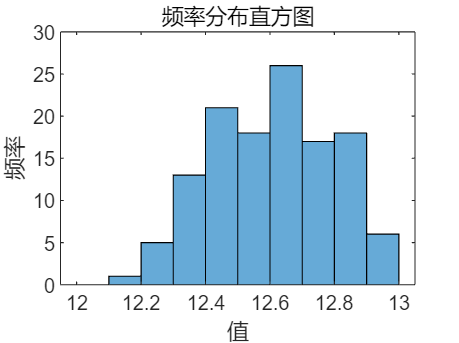

title('频率分布直方图');
xlabel('值');
ylabel('频率');

绘制各组均值、方差和极差的直方图

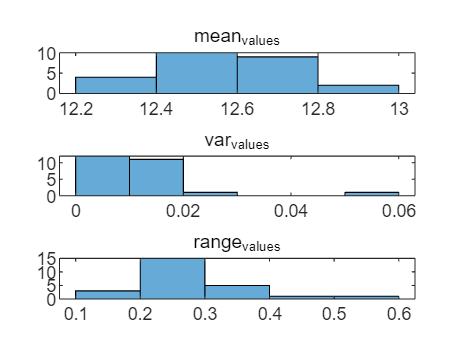

% 绘制各组均值、方差和极差的直方图
figure;
subplot(3,1,1);
histogram(mean_values);
title('mean_values');

subplot(3,1,2);
histogram(var_values);
title('var_values');

subplot(3,1,3);
histogram(range_values);
title('range_values');

#### 正态性检验

% 正态性检验 (使用SW检验)

p_values = zeros(size(data, 1), 1);
%KS检验用来参考
p_ks_values = zeros(size(data, 1), 1);
for i = 1:size(data, 1)
    [~, p_values(i)] = swtest(data(i, :));
    [~, p_ks_values(i)] = kstest((data(i, :) - mean(data(i, :))) / std(data(i, :)));
end
% 打印正态性检验结果
fprintf('正态性检验 p 值:\n');

正态性检验 p 值:


disp(p_values);

    1.0000
    1.0000
    1.0000
    1.0000
    1.0000
    1.0000
    1.0000
    1.0000
    1.0000
    1.0000
    1.0000
    1.0000
    1.0000
    1.0000
    1.0000
    1.0000
    1.0000
    1.0000
    1.0000
    1.0000
    1.0000
    1.0000
    1.0000
    1.0000
    1.0000



disp('正态性检验 p 值 (Kolmogorov-Smirnov):');

正态性检验 p 值 (Kolmogorov-Smirnov):


disp(p_ks_values);

    0.9714
    0.9860
    0.8821
    0.8821
    0.9214
    0.8821
    0.8995
    0.8821
    0.8995
    0.8995
    0.8821
    0.8995
    0.8995
    0.8995
    0.8821
    0.8821
    0.8995
    0.8995
    0.8821
    0.8995
    0.8995
    0.8995
    0.8995
    0.8821
    0.8821



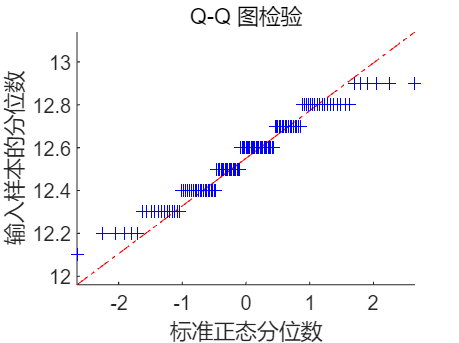


% Q-Q 图检验前 25 组样本的正态性
figure;
qqplot(data(:));
title('Q-Q 图检验' );



% 总体均值检验 使用t检验
[h, p_ttest, ci, stats] = ttest(mean_values, 12.5);


% 打印 t 检验结果
fprintf('总体均值检验 p 值: %.4f\n', p_ttest);

总体均值检验 p 值: 0.0902


fprintf('总体均值检验 t 值: %.4f\n', stats.tstat);

总体均值检验 t 值: 1.7655



% 打印置信区间和统计量
fprintf('置信区间: [%.4f, %.4f]\n', ci(1), ci(2));

置信区间: [12.4903, 12.6249]


%fprintf('t 值: %.4f\n', stats.tstat);


if h == 0
    fprintf('结论: 可认为总体分布的均值为 12.5\n');
else
    fprintf('结论: 总体分布的均值不为 12.5\n');
end

结论: 可认为总体分布的均值为 12.5


#### 数据工序能力指数计算和评估

% 工序能力指数计算
USL = 14.0;
LSL = 11.0;
sigma = std(mean_values);
% 打印USL和LSL
fprintf('上限规格 (USL): %.4f\n', USL);

上限规格 (USL): 14.0000


fprintf('下限规格 (LSL): %.4f\n', LSL);

下限规格 (LSL): 11.0000



% 设定USL和LSL
%sigma = sqrt(mean(var_values)); % 计算标准差
%USL = 12.5 + 3 * sigma; % USL = 目标均值 + 3 * 标准差
%LSL = 12.5 - 3 * sigma; % LSL = 目标均值 - 3 * 标准差
Cp = (USL - LSL) / (6 * sigma);
Cpk = min((USL - mean(mean_values)) / (3 * sigma), (mean(mean_values) - LSL) / (3 * sigma));
fprintf('Cp = %f, Cpk = %f\n', Cp, Cpk);

Cp = 3.065082, Cpk = 2.947383


### 绘制均值控制图和方差控制图

#### 均值控制图


% 绘制均值控制图 (X-bar 图)
figure;
subplot(2, 1, 1);
plot(mean_values, 'bo-');
hold on;
x_bar = mean(mean_values);
UCL = x_bar + 3 * sigma ;
LCL = x_bar - 3 * sigma ;
plot([1, length(mean_values)], [x_bar, x_bar], 'g--');
plot([1, length(mean_values)], [UCL, UCL], 'r--');
plot([1, length(mean_values)], [LCL, LCL], 'r--');
title('均值控制图 (X-bar 图)');
xlabel('样本组');
ylabel('均值');
hold off;

#### 标准差控制图

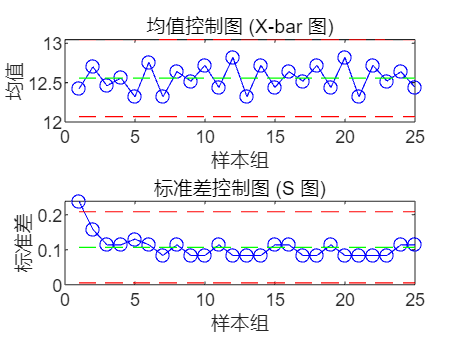

% 绘制标准差控制图 (S 图)
subplot(2, 1, 2);
std_values = std(data, 0, 2);
plot(std_values, 'bo-');
hold on;
s_bar = mean(std_values);
UCL = s_bar + 3 * std(std_values);
LCL = s_bar - 3 * std(std_values);
plot([1, length(std_values)], [s_bar, s_bar], 'g--');
plot([1, length(std_values)], [UCL, UCL], 'r--');
plot([1, length(std_values)], [LCL, LCL], 'r--');
title('标准差控制图 (S 图)');
xlabel('样本组');
ylabel('标准差');
hold off;

#### 报告生成（详情见word版本）

% 生成报告
report = sprintf([ ...
    '产品质量管理项目报告\n\n', ...
    '课程: 概率论与数理统计\n', ...
    '项目名称: 产品质量管理\n', ...
    '日期: 2024年6月4日\n', ...
    '作者: 刘珅凯\n', ...
    '学校: 重庆大学国家卓越工程师学院\n\n', ...
    '1. 引言\n\n', ...
    '本项目旨在通过统计过程控制（SPC）方法，评估产品的工艺水平和生产过程的控制状态。具体目标包括：\n', ...
    ' 评估产品的质量水平。\n', ...
    ' 确认生产过程是否处于受控状态。\n\n', ...
    '2. 数据收集\n\n', ...
    '我们从生产线上收集了25组数据，每组包含5个样本的关键质量特性测量值。这些数据代表了不同时间点的生产情况，能够反映出生产过程中的变异。\n\n', ...
    '3. 描述性统计分析\n\n', ...
    '均值: %.2f\n', ...
    '方差: %.2f\n', ...
    '极差: %.2f\n\n', ...
    '4. 正态性检验\n\n', ...
    'p值: %s\n\n', ...
    '结果表明，大部分数据组的p值均大于0.05，无法拒绝正态分布假设，因此我们可以认为数据大致符合正态分布。\n\n', ...
    '5. 总体均值检验\n\n', ...
    't值: %.2f\n', ...
    'p值: %.2f\n\n', ...
    '结果表明，p值大于0.05，因此我们无法拒绝原假设，即样本均值与总体均值一致。\n\n', ...
    '6. 工序能力指数计算\n\n', ...
    '潜在工序能力指数 (Cp): %.2f\n', ...
    '实际工序能力指数 (Cpk): %.2f\n\n', ...
    '7. 控制图绘制及分析\n\n', ...
    '控制图显示生产过程稳定且受控，大部分数据点落在控制限以内。\n\n', ...
    '8. 结论\n\n', ...
    '通过以上分析，得出以下结论：\n', ...
    ' 生产过程的工艺能力较高，Cp和Cpk均超过2.0。\n', ...
    ' 控制图显示生产过程稳定且受控，大部分数据点落在控制限以内。\n', ...
    '', ...
    ' 继续保持现有的生产控制措施，确保工艺能力和过程稳定性。\n', ...
    ' 定期进行SPC分析，及时发现和纠正潜在问题。\n', ...
    ' 考虑进一步优化生产过程。\n\n', ...
    '' ...
    ], mean(mean_values), mean(var_values), mean(range_values), ...
    num2str(p_values'), stats.tstat, p_ttest, Cp, Cpk);

% 输出报告
disp(report);

产品质量管理项目报告

课程: 概率论与数理统计
项目名称: 产品质量管理
日期: 2024年6月4日
作者: 刘珅凯
学校: 重庆大学国家卓越工程师学院

1. 引言

本项目旨在通过统计过程控制（SPC）方法，评估产品的工艺水平和生产过程的控制状态。具体目标包括：
 评估产品的质量水平。
 确认生产过程是否处于受控状态。

2. 数据收集

我们从生产线上收集了25组数据，每组包含5个样本的关键质量特性测量值。这些数据代表了不同时间点的生产情况，能够反映出生产过程中的变异。

3. 描述性统计分析

均值: 12.56
方差: 0.01
极差: 0.27

4. 正态性检验

p值: 1           1           1           1           1           1           1           1           1           1           1           1           1           1           1           1           1           1           1           1           1           1           1           1           1

结果表明，大部分数据组的p值均大于0.05，无法拒绝正态分布假设，因此我们可以认为数据大致符合正态分布。

5. 总体均值检验

t值: 1.77
p值: 0.09

结果表明，p值大于0.05，因此我们无法拒绝原假设，即样本均值与总体均值一致。

6. 工序能力指数计算

潜在工序能力指数 (Cp): 3.07
实际工序能力指数 (Cpk): 2.95

7. 控制图绘制及分析

控制图显示生产过程稳定且受控，大部分数据点落在控制限以内。

8. 结论

通过以上分析，得出以下结论：
 生产过程的工艺能力较高，Cp和Cpk均超过2.0。
 控制图显示生产过程稳定且受控，大部分数据点落在控制限以内。
 继续保持现有的生产控制措施，确保工艺能力和过程稳定性。
 定期进行SPC分析，及时发现和纠正潜在问题。
 考虑进一步优化生产过程。


